# ЛР 5. Скользящие режимы

Денис Кирбаба R3438

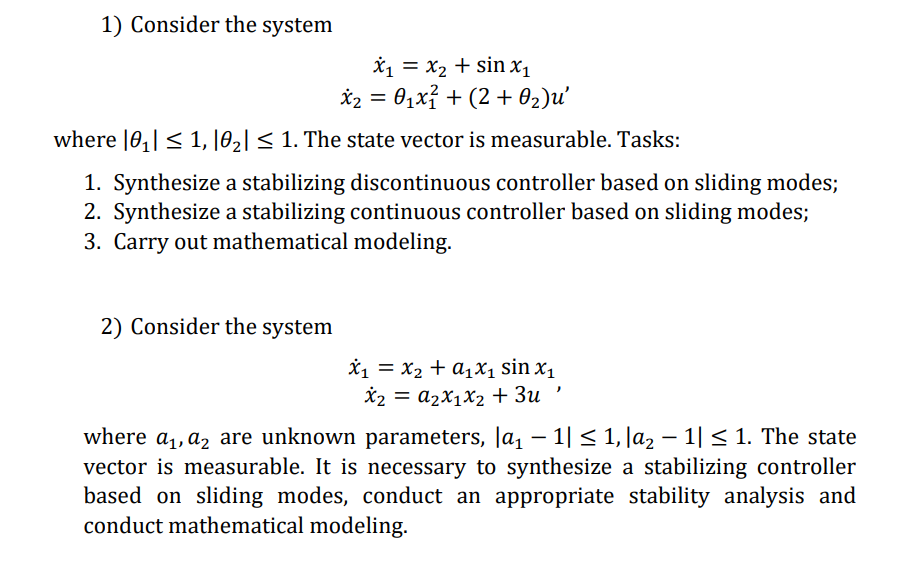

## 1 cистема

### Разрывной закон управления

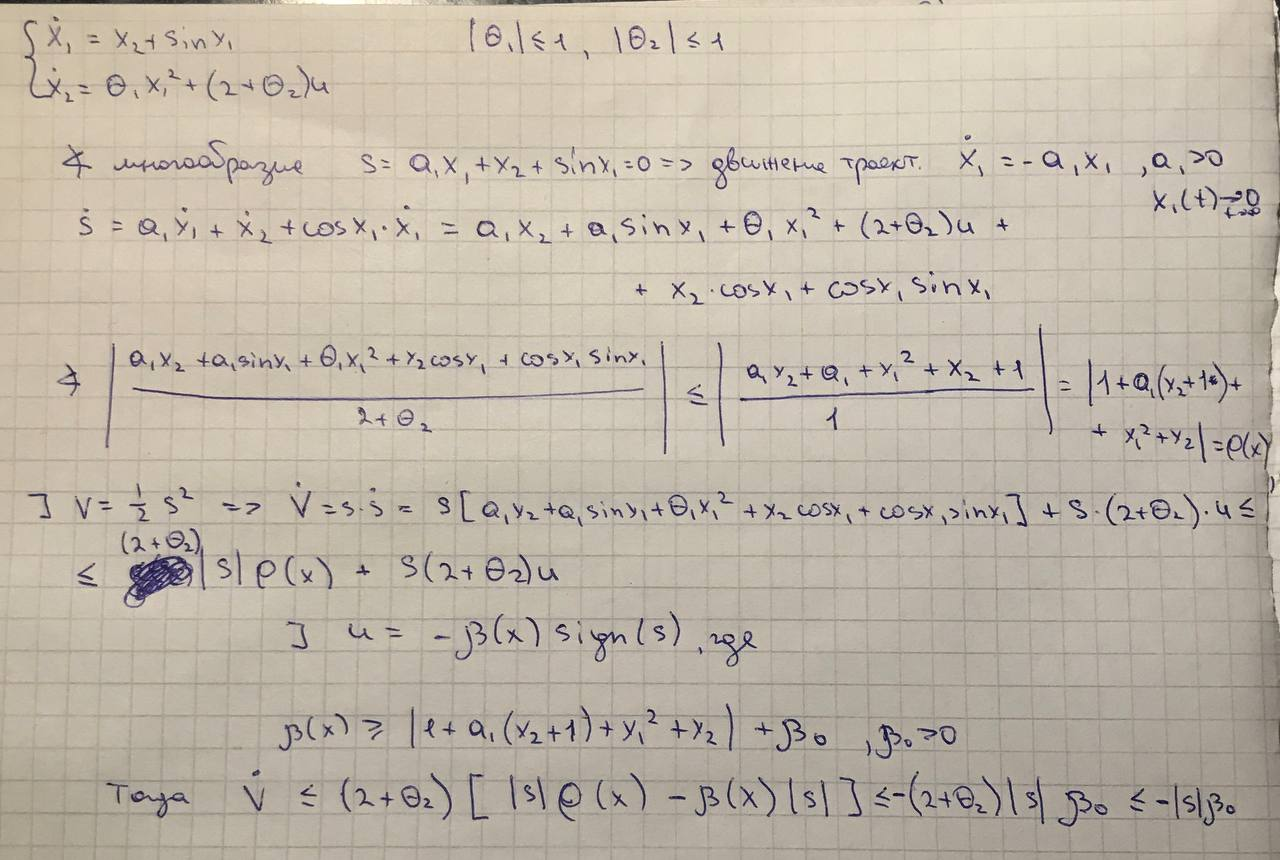

a1 = 5;
theta1 = 0.5;
theta2 = -0.5;
betta0 = 5;

x1_initial = 2;
x2_initial = -3;

control_type = 1;

Tmdl = 5;
n_steps = 10000;

warning off
SimNew = sim("system1.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
x1 = SimNew.out.signals(1).values;
x2 = SimNew.out.signals(2).values;
u = SimNew.out.signals(3).values;

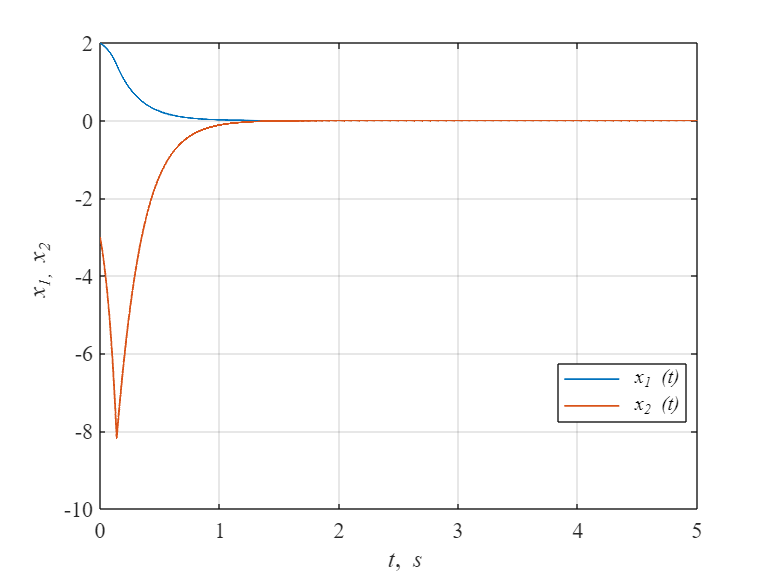

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x1,'LineWidth',1)
hold on
grid on
plot(t,x2,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x_1, x_2')
legend('\it x_1 (t)','\it x_2 (t)','Location','best')

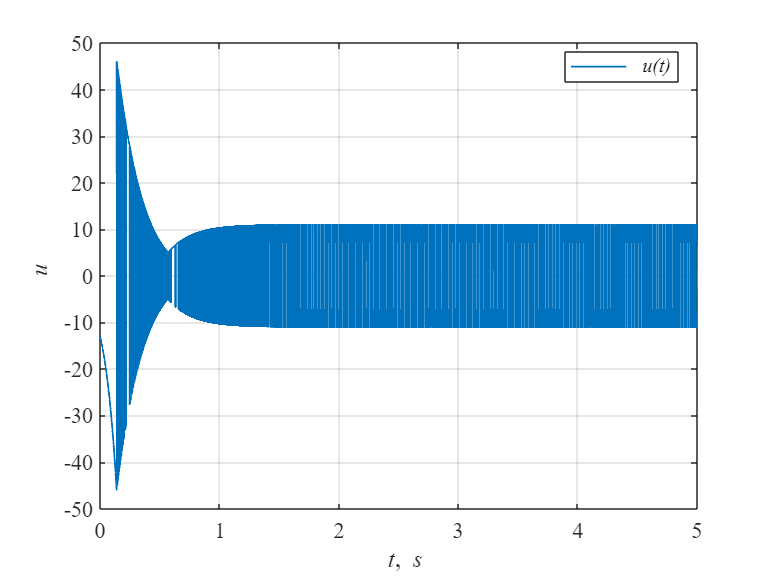

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it u')
legend('\it u(t)','Location','best')

% phase portrait
tspan=[0,Tmdl];
x_lim = [-4; 4];
y_lim = [-4; 4];

[x_init,y_init] = meshgrid(linspace(x_lim(1), x_lim(2), 25), linspace(y_lim(1), y_lim(2), 25));
icond=cell(1,numel(x_init));
for n=1:numel(x_init)
    icond{n}=[x_init(n),y_init(n)];
end

figure;
warning('off')
PhasePlane(@system1_discont,tspan,icond,'scale',2,'Xlim',x_lim,'Ylim',y_lim);

### Непрерывный закон управления

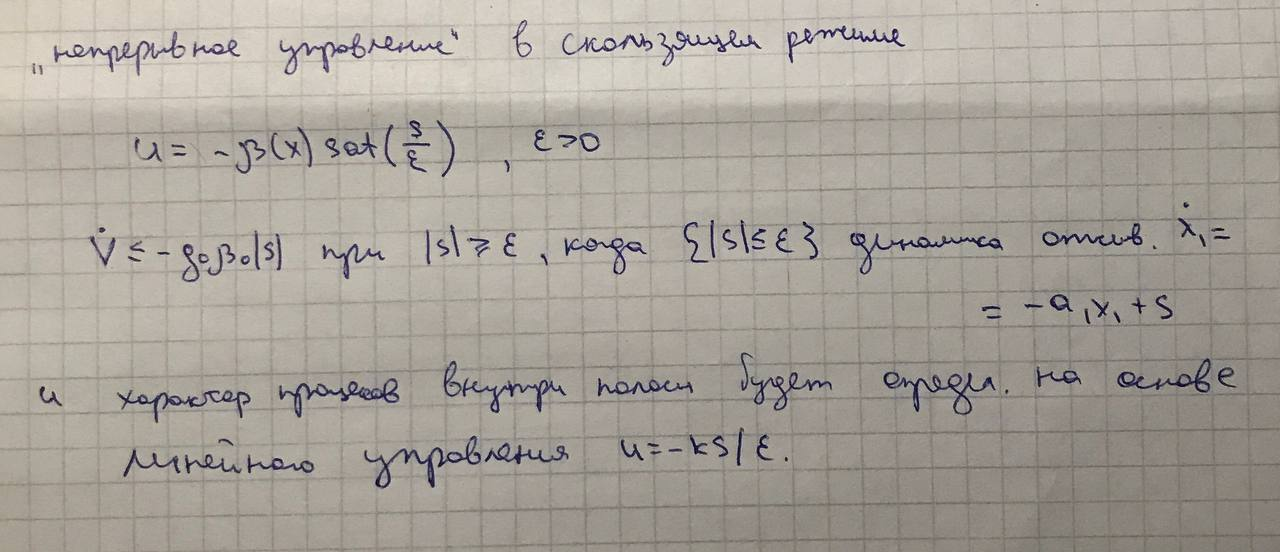

a1 = 5;
theta1 = 0.5;
theta2 = -0.5;
betta0 = 5;
eps = 0.1;

x1_initial = 2;
x2_initial = -3;

control_type = 0;

Tmdl = 5;
n_steps = 10000;

warning off
SimNew = sim("system1.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
x1 = SimNew.out.signals(1).values;
x2 = SimNew.out.signals(2).values;
u = SimNew.out.signals(3).values;

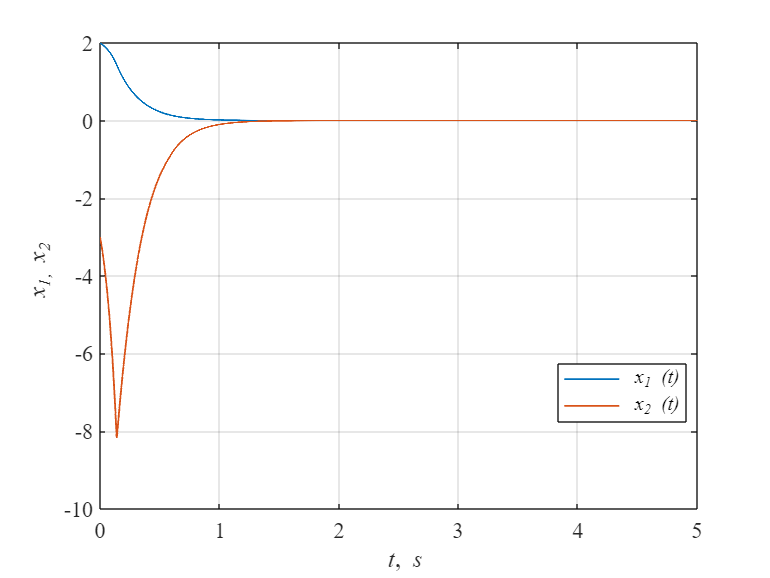

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x1,'LineWidth',1)
hold on
grid on
plot(t,x2,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x_1, x_2')
legend('\it x_1 (t)','\it x_2 (t)','Location','best')

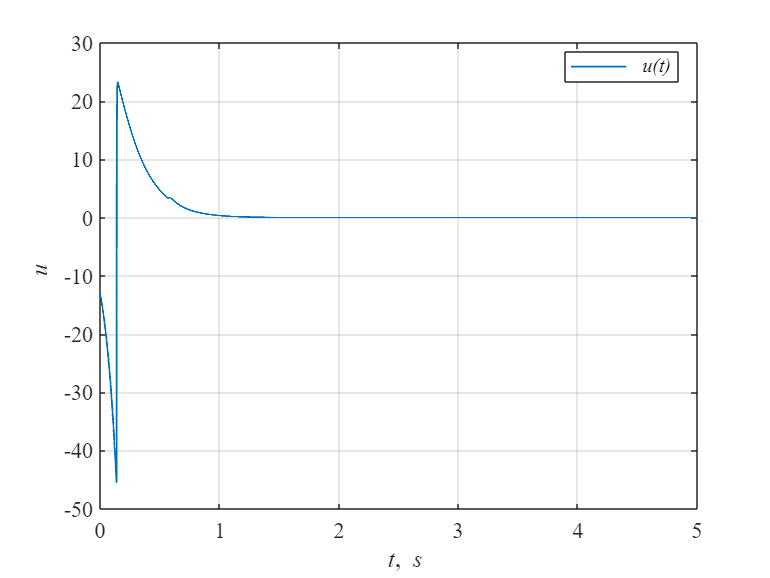

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it u')
legend('\it u(t)','Location','best')

## 2 система

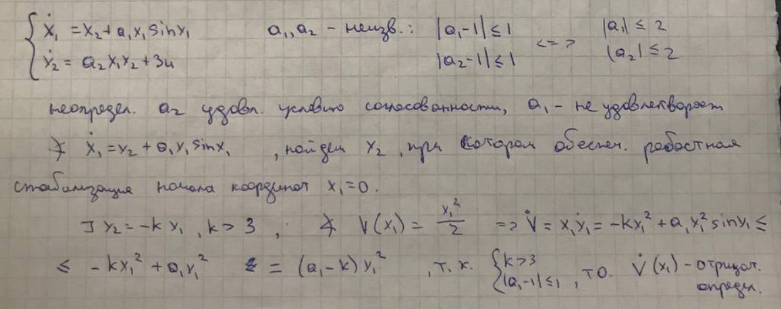

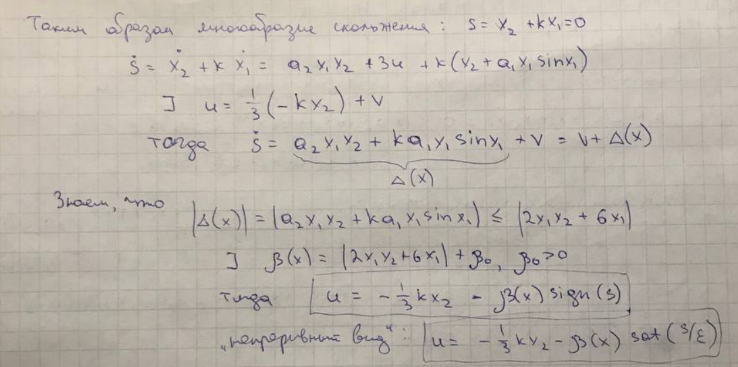

betta0 = 5;
eps = 0.01;

a1 = 1.5;
a2 = -1.5;

k = 3;

x1_initial = 2;
x2_initial = -3;

control_type = 0;

Tmdl = 5;
n_steps = 10000;

warning off
SimNew = sim("system2.slx",'ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.out.time;
x1 = SimNew.out.signals(1).values;
x2 = SimNew.out.signals(2).values;
u = SimNew.out.signals(3).values;

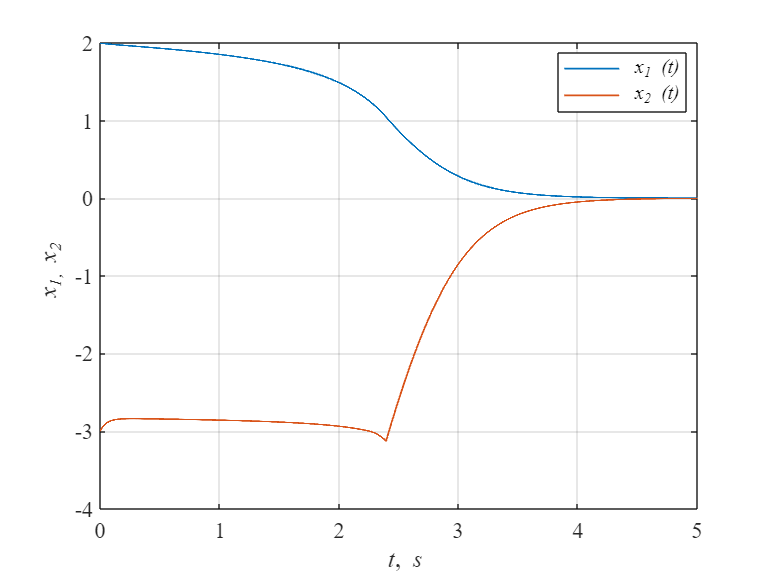

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,x1,'LineWidth',1)
hold on
grid on
plot(t,x2,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\it x_1, x_2')
legend('\it x_1 (t)','\it x_2 (t)','Location','best')

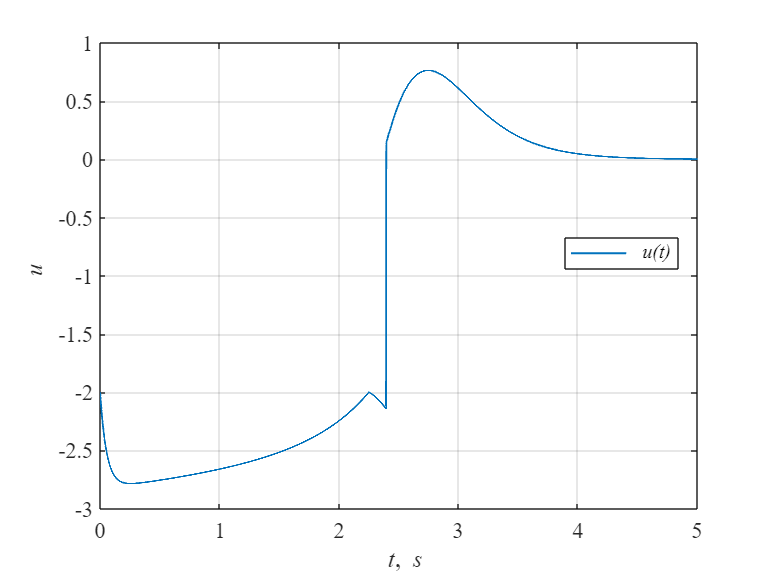

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,u,'LineWidth',1)
hold on
grid on
xlabel('\it t\rm,\it s')
ylabel('\it u')
legend('\it u(t)','Location','best')